**Initial Setup**

clear all
close all
clc

**Parameters**

base_path = '../final_tests/Coupling Darcy-Richards/lagrange_hard_coupling/csv/';
reference = '../tests/richards_initial_tests/benchamark_problem/primal_multi_stage_save/csv/';

files = struct2table(dir(append(base_path, '*.csv')));
files = sortrows(files, 3);

shape = size(files);

**Import files**

%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 4);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["x", "y", "h", "p"];
opts.VariableTypes = ["double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
for j = 1:shape(1)
    name = files.name{j};
    data(j, :, :) = table2array(readtable(append(base_path, name), opts));
end

**Plots**

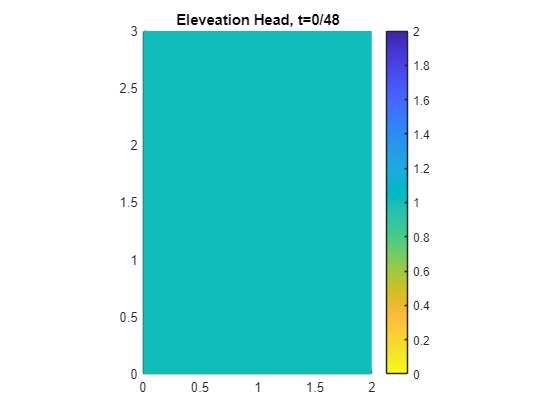

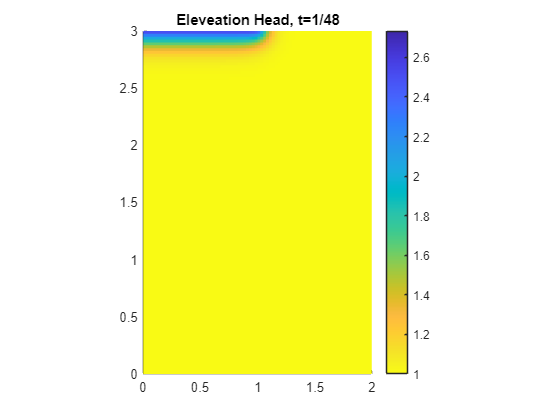

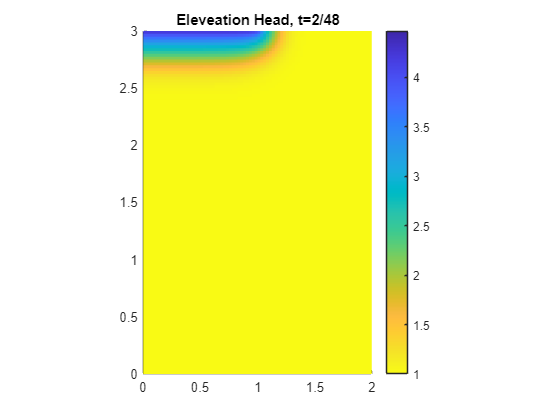

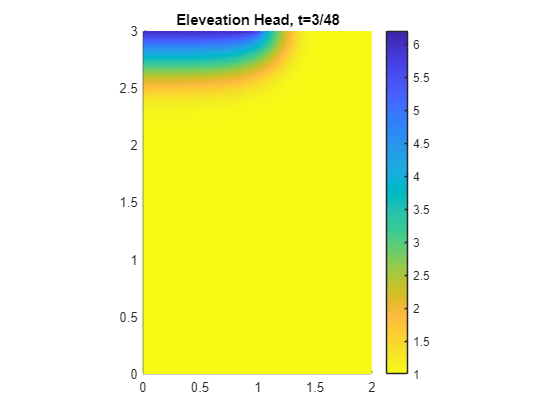

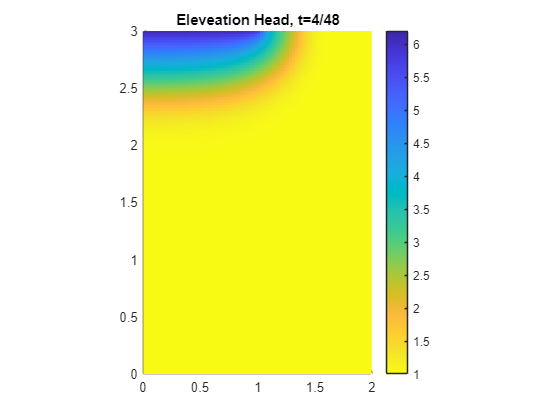

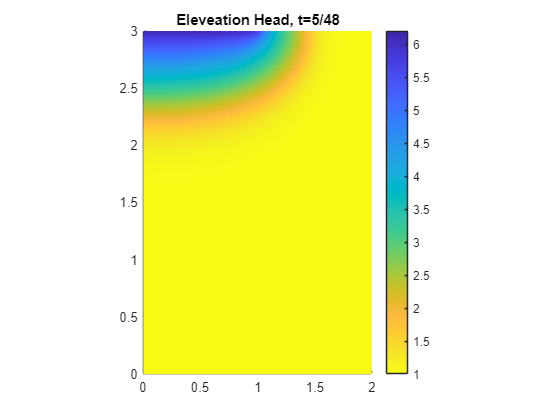

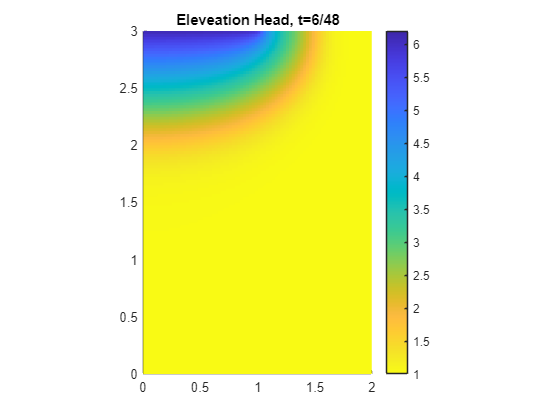

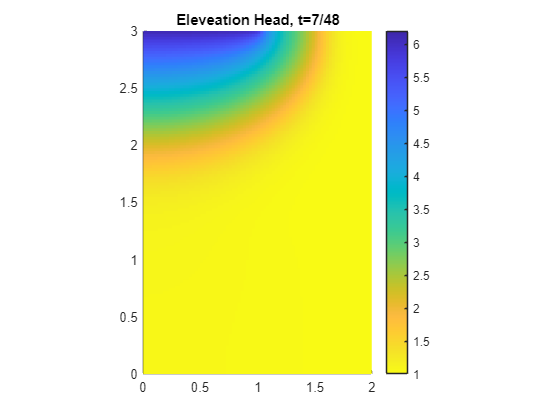

tmp = size( data(end, :, 1) );
N = (sqrt(25 + 24 * (tmp(2) - 1)) - 5) / 12;

for j = 1:shape(1)
    xq = reshape(data(j, :, 1), [2*N+1, 3*N+1]);
    yq = reshape(data(j, :, 2), [2*N+1, 3*N+1]);
    zq = reshape(data(j, :, 3), [2*N+1, 3*N+1]);

    figure
    hold on
    surf(xq,yq,zq, 'EdgeColor','none')
    title(append('Eleveation Head, t=', append(string(j-1), '/48')))
    colormap(flipud(parula))
    colorbar
    axis tight
    daspect([5 5 1])
    hold off
end

post = linspace(0, 3.2, 10);
livs = [linspace(-2, 0, 10), post(2:end)];

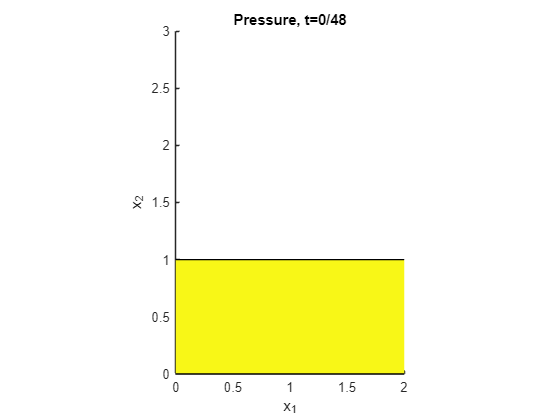

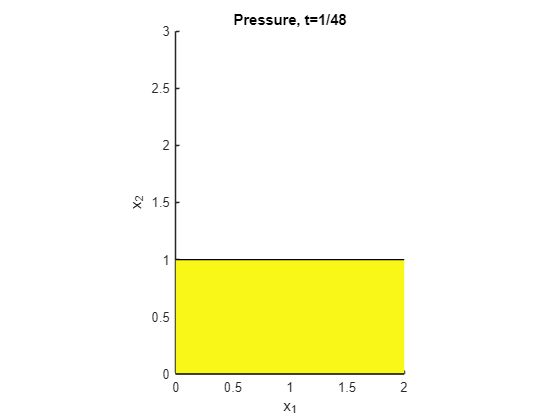

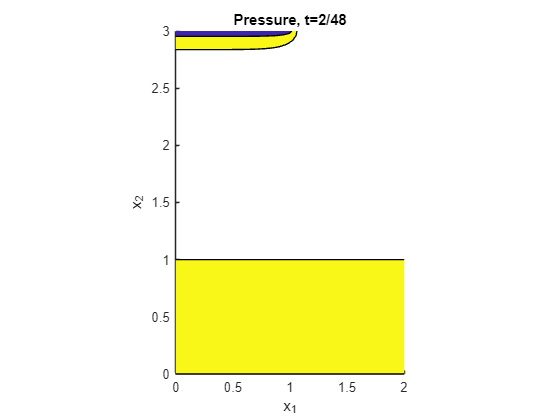

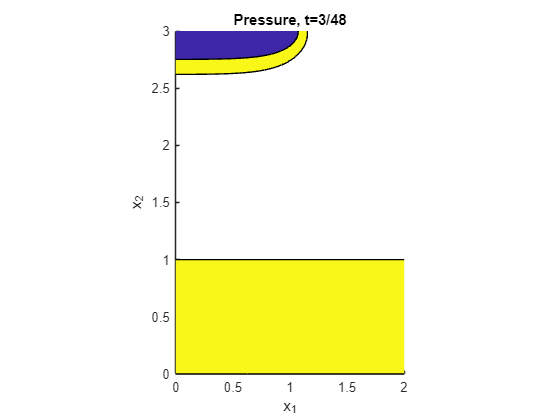

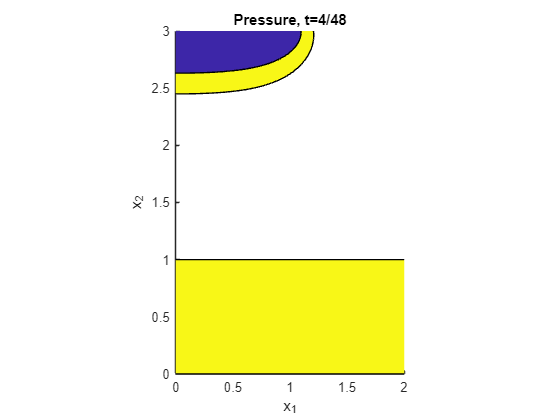

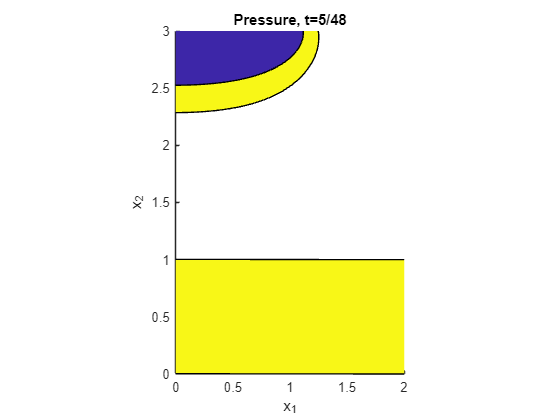

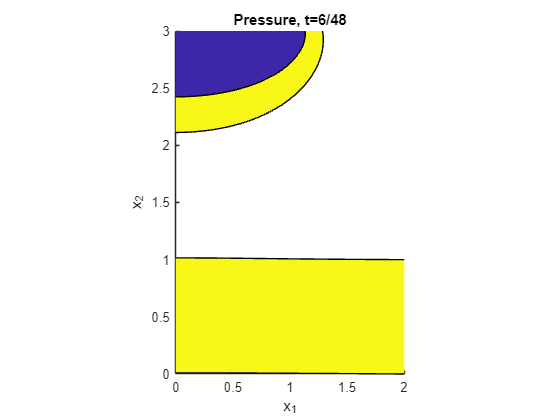

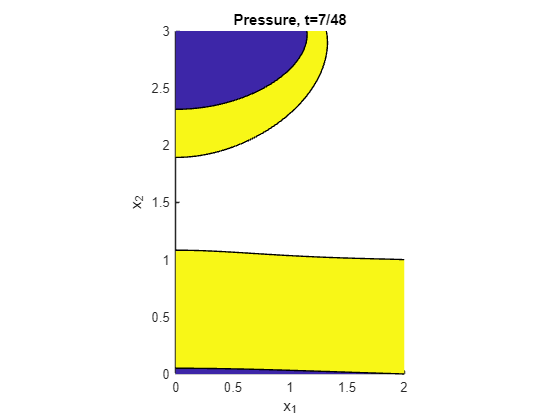

tmp = size( data(end, :, 1) );
N = (sqrt(25 + 24 * (tmp(2) - 1)) - 5) / 12;

for j = 1:shape(1)
    xq = reshape(data(j, :, 1), [2*N+1, 3*N+1]);
    yq = reshape(data(j, :, 2), [2*N+1, 3*N+1]);
    zq = reshape(data(j, :, 3), [2*N+1, 3*N+1])-reshape(data(j, :, 2), [2*N+1, 3*N+1]);

    figure
    hold on
    contourf(xq,yq,zq, [0,1])
    title(append('Pressure, t=', append(string(j-1), '/48')))
    xlabel('x_1')
    ylabel('x_2')
    colormap(flipud(parula))
    axis tight
    daspect([5 5 1])
    hold off
end

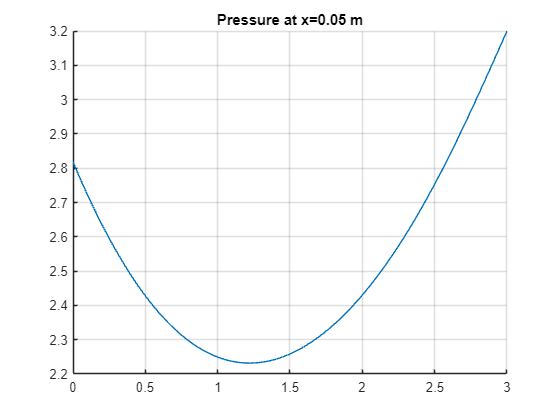

[~, index] = min(abs(xq(:, 1)-0.05));

pressure = reshape(data(end, :, 3), [2*N+1, 3*N+1])-reshape(data(end, :, 2), [2*N+1, 3*N+1]);

figure
hold on
title('Pressure at x=0.05 m')
plot(yq(index, :), pressure(index, :))
grid on
hold off

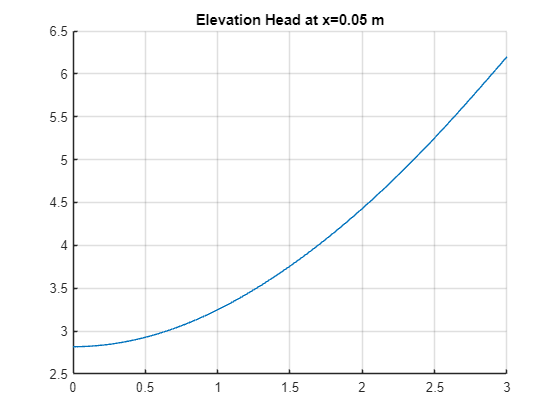

h = reshape(data(end, :, 3), [2*N+1, 3*N+1]);

figure
hold on
plot(yq(index, :), h(index, :))
title('Elevation Head at x=0.05 m')
grid on
hold off